% zverev
% pagina 82

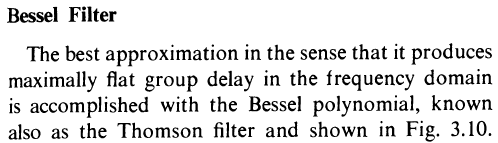

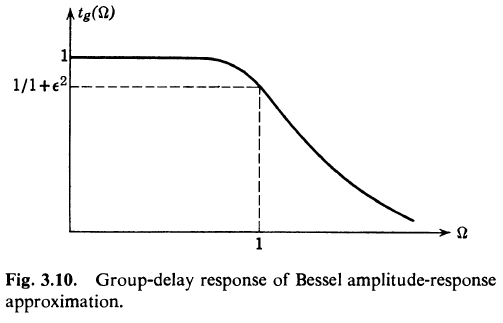

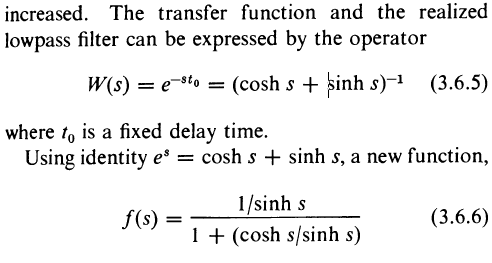

clear all; clc;
syms s;
syms w;

f(s)= 1/(cosh(s)+sinh(s))

$$f(s) = \frac{1}{\cosh\left(s\right)+\sinh\left(s\right)}$$


ezplot(abs(f(j*w)),[0,3]), hold on;

f(s)= 3/(s^2 + 3*s + 3)

$$f(s) = \frac{3}{s^{2}+3\,s+3}$$

ezplot(abs(f(j*w)),[0,3])


f(s)=15/(s^3 + 6*s^2 +15*s+15)

$$f(s) = \frac{15}{s^{3}+6\,s^{2}+15\,s+15}$$

ezplot(abs(f(j*w)),[0,3])

f(s)=105/(s^5+10*s^3+45*s^2+105*s+105)

$$f(s) = \frac{105}{s^{5}+10\,s^{3}+45\,s^{2}+105\,s+105}$$

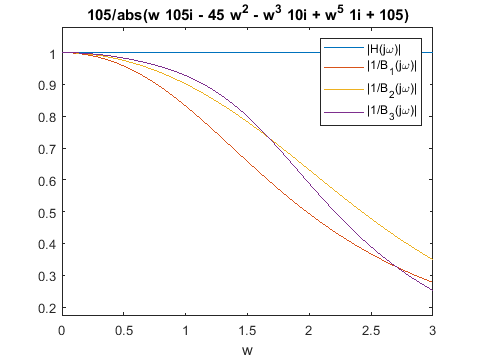

ezplot(abs(f(j*w)),[0,3]), hold off;

legend('|H(j\omega)|','|1/B_1(j\omega)|', ...
                   '|1/B_2(j\omega)|', '|1/B_3(j\omega)|')

fase

leg=[];
f(s)= cosh(s)/sinh(s);
f(w)=imag(simplify(f(j*w),'step',100))

$$f(w) = -\mathrm{real}\left(\cot\left(w\right)\right)$$

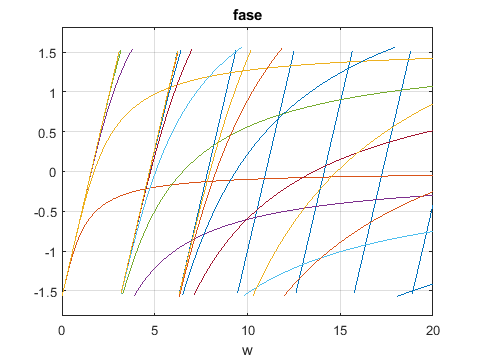

ezplot(atan(f(w)),[0,20]), hold on;
leg(1)='1';

for n=1:9
    f(s)=B(s,n);
    
    f(s)= collect( Par(f(s))/Impar(f(s)) );

    f(w)= simplify(f(j*w)/j,'step',100);

    ezplot(atan(f(w)),[0,20])
    leg(n+1)=num2str(n);
end

hold off;title('fase'), grid on;

%legend('|H(j\omega)|','|1/\b_1(j\omega)|', ...
 %                  '|1/B_2(j\omega)|', '|1/B_3(j\omega)|')

retardo de grupo

f(s)= cosh(s)/sinh(s);
f(w)=diff( atan( simplify(f(j*w)/j,'step',100)) ,w)

$$f(w) = 1$$

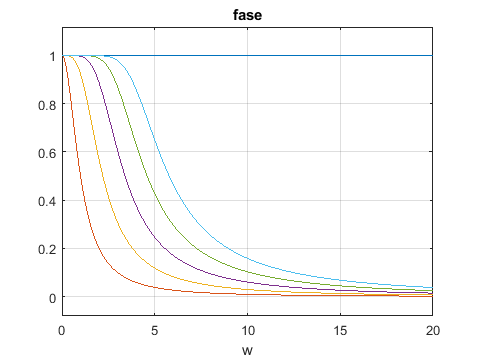

ezplot((f(w)),[0,20]), hold on;

for n=1:5
    clear f(s);

    f(s)=collect(B(s,n));
    
    g(s)= collect( Impar(f(s))/Par(f(s)) );

    h(w)=atan( simplify(1/g(j*w)/j,'step',100) );

    k(w)=diff( h(w),w);

    ezplot(k(w),[0,20])
end   

hold off; title('fase'), grid on;

%legend('|H(j\omega)|','|1/\b_1(j\omega)|', ...
 %                  '|1/B_2(j\omega)|', '|1/B_3(j\omega)|')



bessel

% function T=B(s,n)
%     if n==0
%        T=sym(0);
%     elseif n==1 
%         T=s+1;
%     else 
%         T=(2*n-1)*B(s, n-1 )+s^2*B(s,n-2);
%     end
% end
% 
% function T=Par(F)
%     syms s;
%     T=(subs(F,s)+subs(F,-s))/2;
% end
% 
% function T=Impar(F)
%     syms s;
%     T=(subs(F,s)-subs(F,-s))/2;
% end